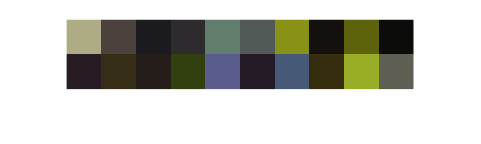

%3.1
clear
load("chips20.mat")
load("illum.mat")
load("xyz.mat")
% Compute Raw
dRaw=xyz'*(chips20.*CIED65)';
%e = R .* I
eD65=ones(1,61).*CIED65;
% Normalization
d=xyz'*(eD65)';
% Apply normalization (d' = d./e)

XYZ_D65_ref=dRaw./d;
showRGB(XYZ_D65_ref')


save("XYZ_D65_ref.mat","XYZ_D65_ref")

%3.2
clear
load("RGB_cal_D65.mat")
load("M_XYZ2RGB.mat")
load("XYZ_D65_ref.mat")
XYZ_cal_D65=(pinv(M_XYZ2RGB)*RGB_cal_D65);

[max,mean]=meanSquare(XYZ_cal_D65,XYZ_D65_ref)

max = 84.1651

mean = 56.8180

%3.3
clear
colorRange=(400:5:700);
load("Ad.mat")
load("xyz.mat")
mycolors = [1 0 0; 0 1 0; 0 0 1];
ax=gca;
ax.ColorOrder=mycolors;

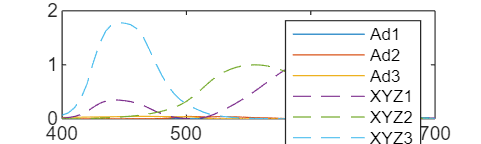

p1=plot(colorRange,Ad);
hold on
p2=plot(colorRange,xyz,'--');
legend([p1 p2],{'Ad1','Ad2','Ad3','XYZ1','XYZ2','XYZ3'})
hold off

%XYZ är mycket högre värden


%3.4
clear
load("RGB_cal_D65.mat")
D=pinv(RGB_cal_D65)';
load("XYZ_D65_ref.mat")
A=D*XYZ_D65_ref';

A =     0.6724    0.4037    0.0420
    0.3169    0.7637   -0.1407
    0.0526   -0.1555    0.9776



A_Est=pinv(A)*RGB_cal_D65;

A_Est =     0.4327    0.2918    0.0148    0.0674   -0.4047   -0.0574    0.5875    0.0728    0.3634    0.0281    0.2967    0.3283    0.1939   -0.0276   -0.1340    0.1978   -0.4069    0.3694    0.4779    0.1474
    0.7980    0.2298    0.1759    0.2427    1.1331    0.6496    0.4441    0.0560    0.2214    0.0552    0.0110    0.0368    0.0597    0.3439    0.7986    0.0735    0.9746   -0.0051    0.6994    0.5157
    0.7062    0.2965    0.1681    0.2393    0.7377    0.5132    0.1795    0.0678    0.0730    0.0511    0.1394    0.0937    0.1100    0.1343    0.7649    0.1691    0.7402    0.0461    0.3208    0.4474


[resMax,resMean]=meanSquare(A_Est,XYZ_D65_ref);


The estimated A matrix has a lower max and mean value, and is thus a closer representation.

%3.5
A=Optimize_poly(RGB_cal_D65,XYZ_D65_ref);
XYZ_est=Polynomial_regression(RGB_cal_D65,A);

[resMax,resMean]=meanSquare(XYZ_est,XYZ_D65_ref)

resMax = 0.2372

resMean = 0.0811

Poly function seems crazy accurate compared to other solutions.